# Parcial 1. Análisis Numérico y Computación Científica

Juan Manuel Ramirez Osuna

Una de las aplicaciones de la interpolación polinomial consiste en emplear polinomios obtenidos mediante técnicas como polinomios de Lagrange o splines cúbicos. La siguiente es la “función de jorobas integradas” que usa Matlab para demostrar algunas de sus capacidades numéricas: 


$$f(x) = \frac{1}{(x-0.3)^2+0.01}+ \frac{1}{(x-0.9)^2+0.04}$$


La función de jorobas muestra regiones tanto llanas como escarpadas a lo largo de un rango relativamente corto de 𝑥. Genere valores de esta función en el rango de 𝑥 = 0 a 1 y:

syms x
xp1 = 0:0.01:0.25

xp1 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500


xp2 = 0.25:0.01:0.75

xp2 =     0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000    0.5100    0.5200    0.5300    0.5400    0.5500    0.5600    0.5700    0.5800    0.5900    0.6000    0.6100    0.6200    0.6300    0.6400    0.6500    0.6600    0.6700    0.6800    0.6900    0.7000    0.7100    0.7200    0.7300    0.7400


xp3 = 0.75:0.01:1

xp3 =     0.7500    0.7600    0.7700    0.7800    0.7900    0.8000    0.8100    0.8200    0.8300    0.8400    0.8500    0.8600    0.8700    0.8800    0.8900    0.9000    0.9100    0.9200    0.9300    0.9400    0.9500    0.9600    0.9700    0.9800    0.9900    1.0000


yp1 = 1./((xp1-0.3).^2+0.01)+1./((xp1-0.9).^2+0.04)

yp1 =    11.1765   11.8288   12.5401   13.3176   14.1693   15.1046   16.1341   17.2702   18.5270   19.9209   21.4706   23.1978   25.1272   27.2870   29.7091   32.4290   35.4856   38.9202   42.7744   47.0868   51.8868   57.1862   62.9661   69.1595   75.6320   82.1622


yp2 = 1./((xp2-0.3).^2+0.01)+1./((xp2-0.9).^2+0.04)

yp2 =    82.1622   88.4311   94.0320   98.5101  101.4365  102.5000  101.5866   98.8106   94.4836   89.0350   82.9197   76.5451   70.2303   64.1973   58.5808   53.4483   48.8190   44.6818   41.0076   37.7583   34.8929   32.3707   30.1534   28.2060   26.4974   25.0000   23.6899   22.5463   21.5512   20.6891   19.9469   19.3133   18.7786   18.3347   17.9745   17.6923   17.4831   17.3427   17.2678   17.2555   17.3033   17.4092   17.5716   17.7889   18.0596   18.3824   18.7554   19.1770   19.6446   20.1555


yp3 = 1./((xp3-0.3).^2+0.01)+1./((xp3-0.9).^2+0.04)

yp3 =    20.7059   21.2912   21.9056   22.5421   23.1923   23.8462   24.4924   25.1181   25.7093   26.2514   26.7294   27.1287   27.4358   27.6393   27.7302   27.7027   27.5548   27.2880   26.9075   26.4217   25.8416   25.1799   24.4508   23.6686   22.8472   22.0000


fp(x) =  1./((x-0.3).^2+0.01)+1./((x-0.9).^2+0.04)

$$fp(x) = \frac{1}{{\left(x-\frac{9}{10}\right)}^{2}+\frac{1}{25}}+\frac{1}{{\left(x-\frac{3}{10}\right)}^{2}+\frac{1}{100}}$$

fplot(fp)
hold on

1. Ajuste la función mediante polinomios de interpolación de Lagrange comprobando, gráficamente, que la interpolación aproxima de forma adecuada la curva original.

fp11(x) = interpolacion_lagrange(xp1,yp1)

fp12(x) = interpolacion_lagrange(xp2,yp2)

fp13(x) = interpolacion_lagrange(xp3,yp3)

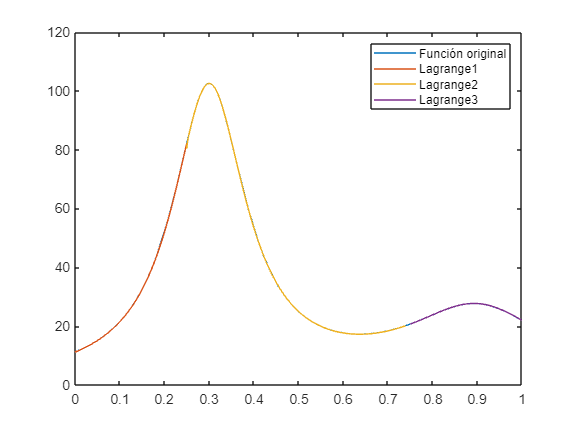

fplot(fp11, [0 0.25])
fplot(fp12, [0.25 0.74])
fplot(fp13, [0.75 1])
xlim([0 1])
ylim([0 120])
legend('Función original', 'Lagrange1', 'Lagrange2', 'Lagrange3')
hold off

Graficamente se puede observar que dentro del rango deseado (0 a 1) la interpolacion se asemeja a la funcion objetivo en valores intermedios, al acercarse a los puntos extremos del rango la interpolacion empieza a presentar fuertes fluctuaciones. De este modo se opto por realizar una interpolacion segmentada dividiendo la funcion en 3 partes. Debido a pruebas realizadas anterioremente para los siguientes puntos, y que no se pegar funciones, se mantendra un unico rango para 0.25 a 0.75 y de esta manera se generan otros dos rangos para 0 a 0.25 y 0.75 a 1.

2. A partir de la interpolación obtenida, calcule el valor de 𝑥 que se obtiene para 𝑓(𝑥) = 45.

fp2(x) = fp12 - 45

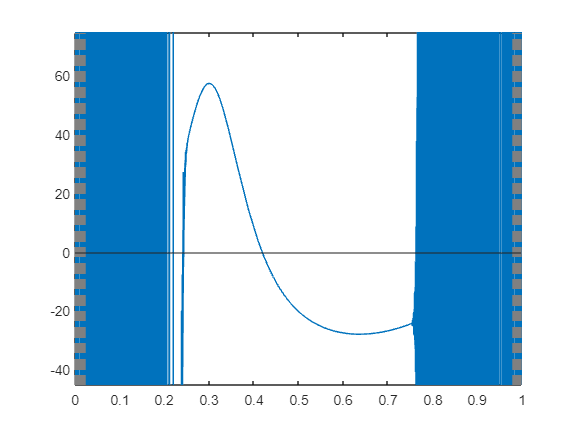

fplot(fp2)
yline(0)
xlim([0.25 0.75])
ylim([0-45 120-45])


c2 = falsa_posicion(fp2, 0.25, 0.75, 0.00001)

$$c2 = 0.41918808512247796919663400828317$$

vpa(fp(c2))

$$ans = 44.999999604732621431224868093971$$

Restando el valor deseado a la funcion para realizar una busqueda de raices se emplea el metodo de falsa posicion. Se realiza una busqueda empezando en 0.25 y 0.75 para que la convergencia ocurra en un punto que estable de la interpolacion. De este modo se encuentra que el x deseado se ubica aproximadamente en 0.41919.

3. Usando una estrategia diferente a la del punto 2, calcule el valor de 𝑥 que se obtiene para 𝑓(𝑥) = 22.

fp3(x) = fp12 - 22

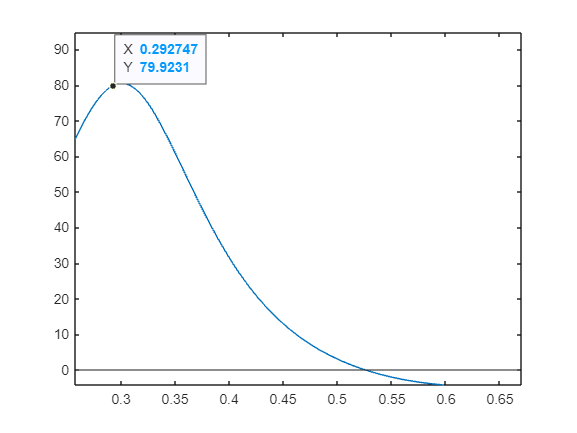

fplot(fp3)
yline(0)
xlim([0.25 0.75])
ylim([0-22 120-22])


c3 = newton_raphson(fp3, 0.5, 0.00001)

$$c3 = 0.52531420241025482891804945681869$$

vpa(fp(c3))

$$ans = 22.000000000004056632722041684866$$

Restando el valor deseado a la funcion para realizar una busqueda de raices se emplea el metodo de newton_rahpson. Se realiza una busqueda empezando en 0.5 esperando que al usar un punto medio del rango la pendiente mantenga el valor objetivo entre el dominio deseado. De este modo se encuentra que el x deseado se ubica aproximadamente en 0.5253.